## Problem 2

### Part a

Reformulated State Space Model:

m1 = 1;
m2 = 1;
k = 1;

A = [0 0 1 0
        0 0 0 1
      -k/m1 k/m1 0 0
       k/m2 -k/m2 0 0];

B_dist = [ 0    0
      0    0
    1/m1   0
      0  1/m2];

B = [ 0
      0 
    1/m1
      0 ];

C = [ 0 1 0 0];

D = [0 0];

ss_sys = ss(A,B_dist,C,D) %State Space system

ss_sys =
 
  A = 
       x1  x2  x3  x4
   x1   0   0   1   0
   x2   0   0   0   1
   x3  -1   1   0   0
   x4   1  -1   0   0
 
  B = 
       u1  u2
   x1   0   0
   x2   0   0
   x3   1   0
   x4   0   1
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.



System Transfer Function:

[num, den] = ss2tf(A,B_dist,C,D,1);

tf_sys = tf(num,den)

tf_sys =
 
                           1
  ----------------------------------------------------
  s^4 - 1.89e-17 s^3 + 2 s^2 - 1.408e-16 s - 3.263e-32
 
Continuous-time transfer function.



### Part b

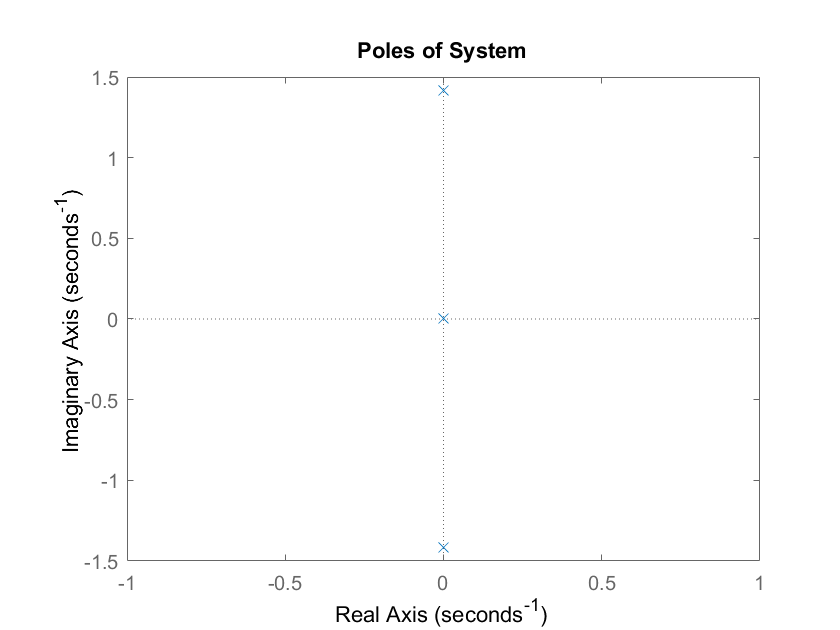

figure 
pzmap(tf_sys)
xlim([-1 1])
title('Poles of System')

### Part c

Choose transient properties:

POS = 10; %10 percent overshoot
ST = 1; %Settling time of 1 second
Tol_frac = 0.02; %Tolerance fraction of 2%
Ts = 1; %Settling time is 1 second

DR = -log(POS/100)/sqrt(pi^2 + log(POS/100)^2) %Damping ratio as function of percent overshoot

DR = 0.5912

Wn = -log(Tol_frac*sqrt(1-DR^2))/(DR*Ts) %Natural frequency from damping ratio and settling time

Wn = 6.9813

Find Poles from $\zeta$ and $\omega_n$

beta = acos(DR)

beta = 0.9383

P1 = -Wn*cos(beta) + 1i*Wn*sin(beta)

P1 = -4.1270 + 5.6308i

P2 = conj(P1);

P3 = real(P1)*10

P3 = -41.2700

P4 = P3*11/10;

K = place(A,B,[P1 P2 P3 P4])

K = 	1.0e+04 *

    0.2636    8.8677    0.0095    1.9593


Full State Feedback Controller

%Simulation Setup
d = 0; %Magnitude of the step disturbance

Dis_Vec = [0
           0
           0
           1/m2];

x0 = [1 2 0 0]';

tstop = 3;

%Run Simulink Model for the full state feedback regulation controller
%with step disturbance input
simout = sim('FSF_w_disturbance.slx');

Plot results

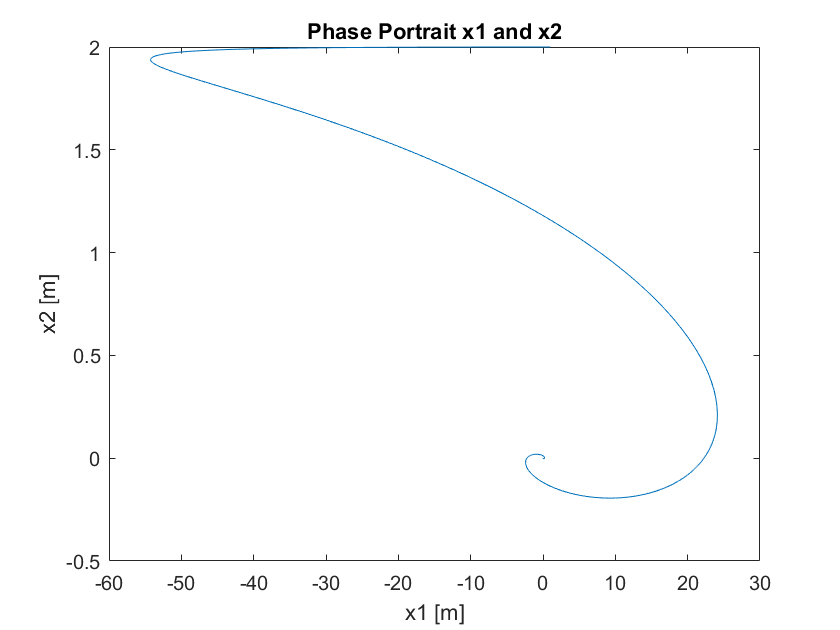

figure
x1 = simout.x(:,1);
x2 = simout.x(:,2);
plot(x1,x2)

xlabel('x1 [m]')
ylabel('x2 [m]')
title('Phase Portrait x1 and x2')

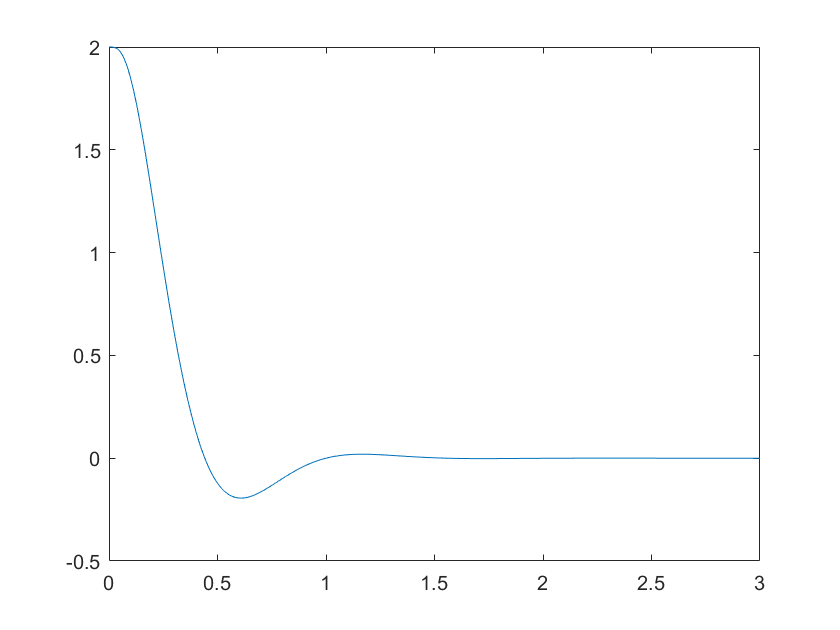


figure
plot(simout.tout,x2)